# 2 DOF Parametric Duffing Oscillator

We reproduce results for example of a 2DOF coupled oscillator system with parametric excitation as given in Szabelski, K. & Warminki, J. Vibration of a Non-Linear Self-Excited System with Two Degrees of Freedomunder External and Parametric Excitation.Nonlinear Dynamics 1997 14:114,23–36 (1 1997). [https://doi.org/10.1023/A:1008227315259](https://doi.org/10.1023/A:1008227315259)

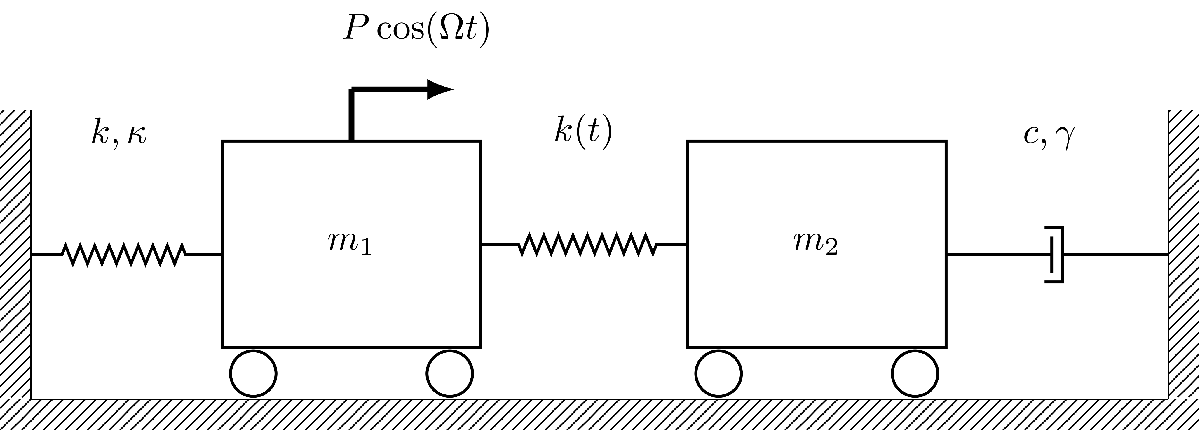

The negative linear damping leads to exponentially growing amplitudes, the effect of which is balanced with positive nonlinear damping which starts contributing at significant oscillation amplitudes.

clear all; close all; clc

## Generate model

[M,C,K,fnl,fext] = build_model();


## Dynamical system setup

We consider the forced  and parametrically excited system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{g}(\mathbf{x},\dot{\mathbf{x}},\Omega t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{G}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{g}(\mathbf{x, \dot{x}},\phi)\\
\mathbf{0}
\end{array}\right]$$


% Dynamical System
DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

## Add forcing

The dynamical system is forced externally and parametrically with $\mathbf{g(x},\Omega t) = 
4 \mu \left[\begin{array}{cc} k & -k \\ -k &  k \end{array}\right] \cos(2\Omega t) \mathbf{x} 
+
\left[\begin{array}{cc}    q \cos (\Omega t )   \\ 0\end{array}\right]$

DS.add_forcing(fext,1e-1);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W] = DS.linear_spectral_analysis();


 The first 4 nonzero eigenvalues are given as 
   0.0037 + 0.5463i
   0.0037 - 0.5463i
   0.0013 + 2.5887i
   0.0013 - 2.5887i



#### Choose Master subspace (perform resonance analysis)

S = SSM(DS);
set(S.Options, 'reltol', 0.5,'notation','multiindex')

%Choose Master subspace
masterModes = [3,4];
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     1     1
     1     1

These are in resonance with the follwing eigenvalues of the slave subspace
   0.0037 + 0.5463i
   0.0037 - 0.5463i

sigma_out = 2
sigma_in = 1


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 5; % Approximation order

setup options

outdof = [1,2];
set(S.Options, 'reltol', 0.5,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 80, 'nPar',600, 'nPsi', 80, 'rhoScale', 4 )
set(S.FRCOptions, 'method','level set') % 'continuation ep'
set(S.FRCOptions, 'outdof',outdof)
set(S.FRCOptions,'coordinates','cartesian')

choose frequency range around the master mode frequency


omega0 = imag(S.E.spectrum(1));
OmegaRange =omega0*[0.95 1.1];

Extract forced response curve

*****************************************
Calculating FRC using SSM with master subspace: [3  4]
(near) outer resonance detected for the following combination of master eigenvalues
     1     1
     1     1

These are in resonance with the follwing eigenvalues of the slave subspace
   0.0037 + 0.5463i
   0.0037 - 0.5463i

sigma_out = 2
sigma_in = 1
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.11E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.25E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 1.46E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 1.75E-02 MB
gamma = 
  -0.0022 + 0.0038i
   0.0000 - 0.0000i



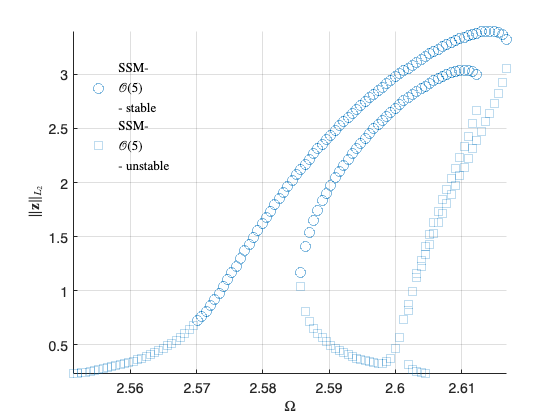

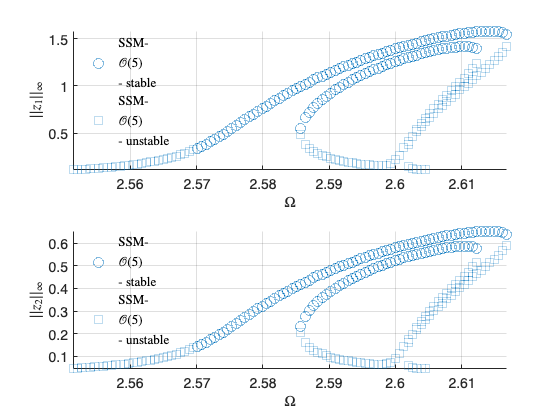

Total time spent on FRC computation upto O(5) = 00:00:28


startFRCSSM = tic;
FRC = S.extract_FRC('freq',OmegaRange,order);

figFRC = gcf;
timings.FRCSSM = toc(startFRCSSM)

timings = struct with fields:
    FRCSSM: 29.3591


## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>

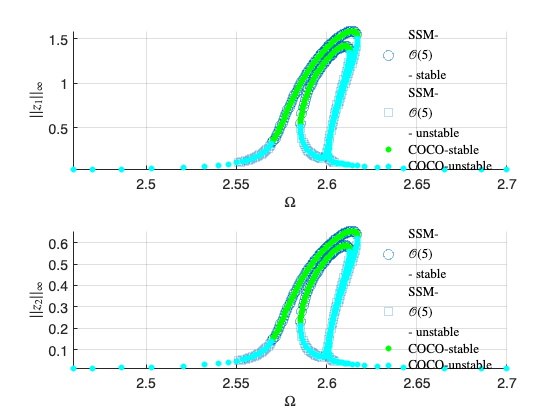


 Run='FRC0.1': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          2.03e-02  5.35e+00    0.0    0.0    0.0
   1   1  3.59e-01  9.75e-01  1.30e-02  5.24e+00    0.0    0.0    0.0
   2   1  5.14e-01  6.26e-01  6.33e-03  5.16e+00    0.0    0.1    0.0
   3   1  9.78e-01  3.04e-01  1.37e-04  5.10e+00    0.0    0.1    0.0
   4   1  1.00e+00  6.62e-03  4.22e-11  5.10e+00    0.0    0.1    0.0
   5   1  1.00e+00  7.63e-09  3.03e-16  5.10e+00    0.1    0.2    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:00   5.0981e+00      1  EP      2.4593e+00   2.5549e+00   1.0000e-01   2.3797e-02   1.1582e-02
   10  00:00:03   6.8076e+00      2          2.5558e+00   2.4584e+00   1.0000e-01   1.3156e-01   5.7213e-02
   20  00:00:04   9.8632e+00      3          2.5683e+0

nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','forward')
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'NTST', 70,'PtMX',350); 

figure(figFRC)
hold on
startcoco = tic;
bd3 = coco.extract_FRC(OmegaRange);

timings.cocoFRC = toc(startcoco)

timings = struct with fields:
     FRCSSM: 29.3591
    cocoFRC: 36.5044
